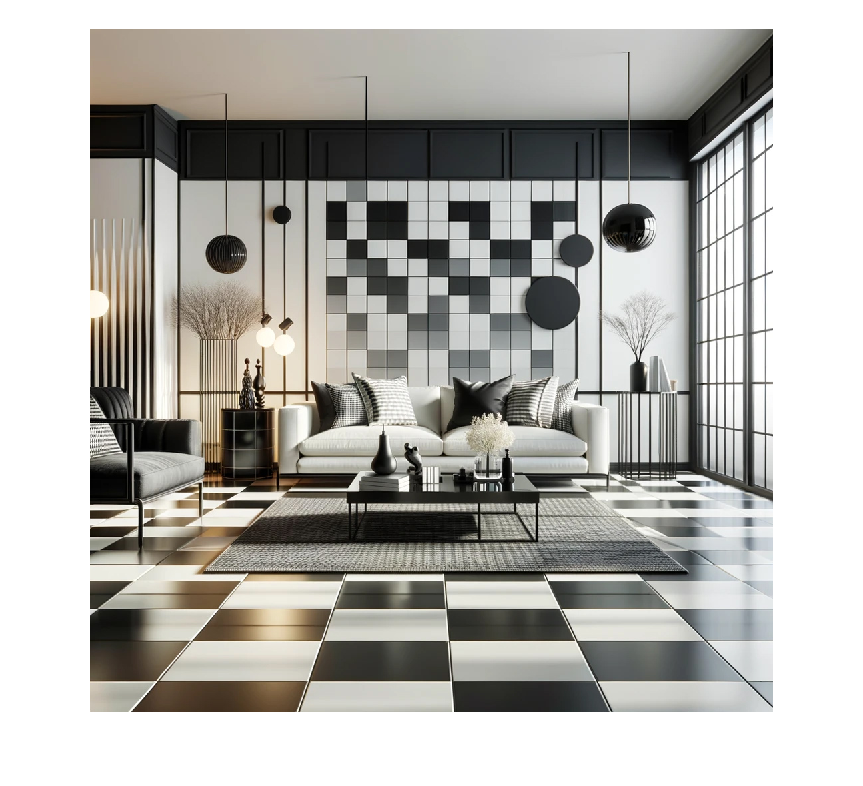

clear all;
% Bild laden
bildmatrix = imread('wohnzimmer.jpg');
imshow(bildmatrix);

figure;
% Parameter für die Wellen
wellenlaenge = 750; % Beispielwert
amplitude = 8; % Beispielwert

% Funktion aufrufen
disp(sin(2 * pi * 383 / 750))

   -0.0670



disp(round(8 * sin(2 * pi * 383 / 750)))

    -1



ergebnis = wellenEffekt(bildmatrix, wellenlaenge, amplitude);

     8

    -1

     1

     0

     9

    -1

     1

     0

    10

    -1

     1

     0

    11

    -1

     1

     0

    12

    -1

     1

     0

    13

    -1

     1

     0

    14

    -1

     1

     0

    15

    -1

     1

     0

    16

    -1

     1

     0

    17

    -1

     1

     0

    18

    -1

     1

     0

    19

    -1

     1

     0

    20

    -1

     1

     0

    21

    -1

     1

     0

    22

    -1

     1

     0

    23

    -2

     1

    -1

    23

    -2

     2

     0

    24

    -2

     1

    -1

    24

    -2

     2

     0

    25

    -2

     1

    -1

    25

    -2

     2

     0

    26

    -2

     1

    -1

    26

    -2

     2

     0

    27

    -2

     1

    -1

    27

    -2

     2

     0

    28

    -2

     1

    -1

    28

    -2

     2

     0

    29

    -2

     1

    -1

    29

    -2

     2

     0

    30

    -2

     1

    -1

    30

    -2

     2

     0

    31



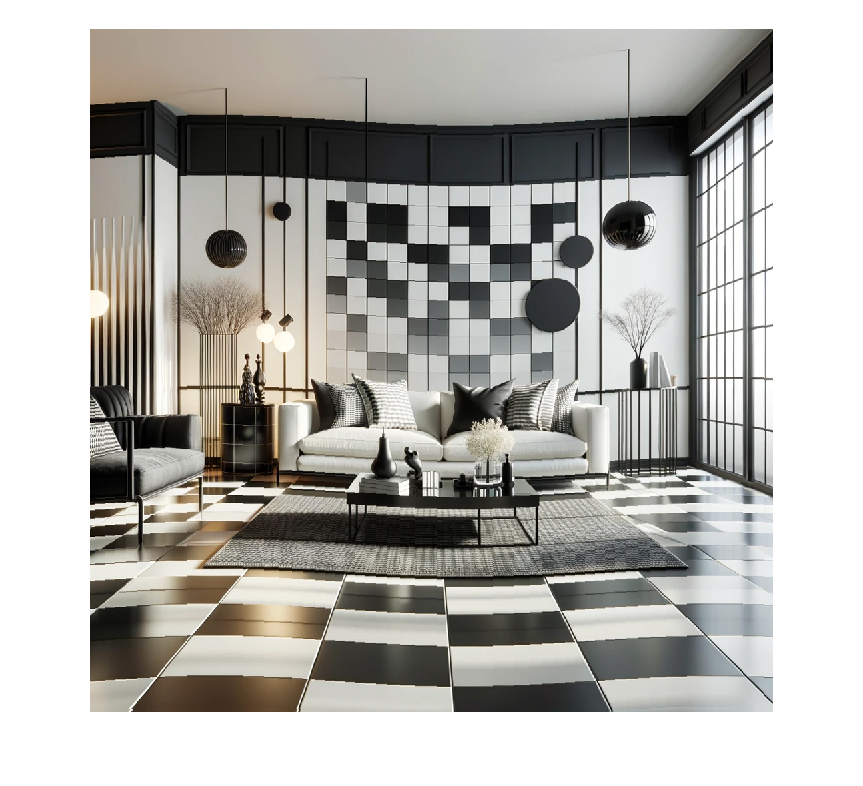

imshow(ergebnis);

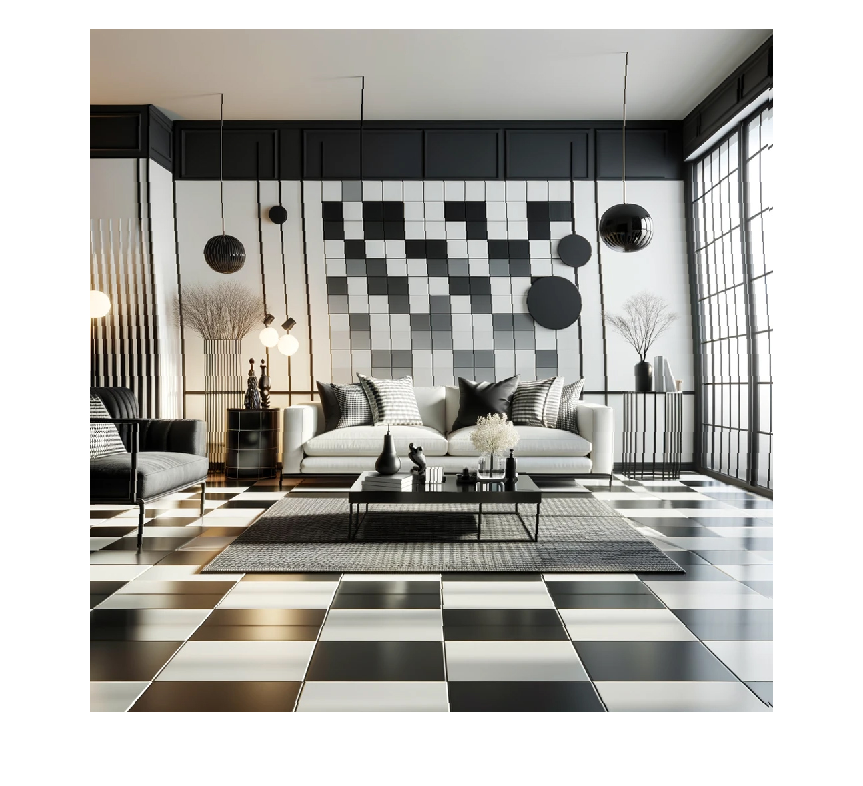

figure;
ergebnis2 = wellenEffekt2(bildmatrix, wellenlaenge, amplitude);
imshow(ergebnis2);

% Ergebnis speichern
imwrite(ergebnis, 'ergebnisbild.jpg');
disp(8*sin(2*pi*8/750))

    0.5358



disp(round(8*sin(2*pi*8/750)))

     1



disp(size(bildmatrix,1));

        1024



disp(size(bildmatrix,2));

        1024



x = linspace(0, 4*pi, 1000); % x-Werte von 0 bis 4*pi
disp(x)

         0    0.0126    0.0252    0.0377    0.0503    0.0629    0.0755    0.0881    0.1006    0.1132    0.1258    0.1384    0.1509    0.1635    0.1761    0.1887    0.2013    0.2138    0.2264    0.2390    0.2516    0.2642    0.2767    0.2893    0.3019    0.3145    0.3271    0.3396    0.3522    0.3648    0.3774    0.3899    0.4025    0.4151    0.4277    0.4403    0.4528    0.4654    0.4780    0.4906    0.5032    0.5157    0.5283    0.5409    0.5535    0.5661    0.5786    0.5912    0.6038    0.6164    0.6289    0.6415    0.6541    0.6667    0.6793    0.6918    0.7044    0.7170    0.7296    0.7422    0.7547    0.7673    0.7799    0.7925    0.8051    0.8176    0.8302    0.8428    0.8554    0.8679    0.8805    0.8931    0.9057    0.9183    0.9308    0.9434    0.9560    0.9686    0.9812    0.9937    1.0063    1.0189    1.0315    1.0441    1.0566    1.0692    1.0818    1.0944    1.1069    1.1195    1.1321    1.1447    1.1573    1.1698    1.1824    1.1950    1.2076    1.2202    1.2327    1.2453

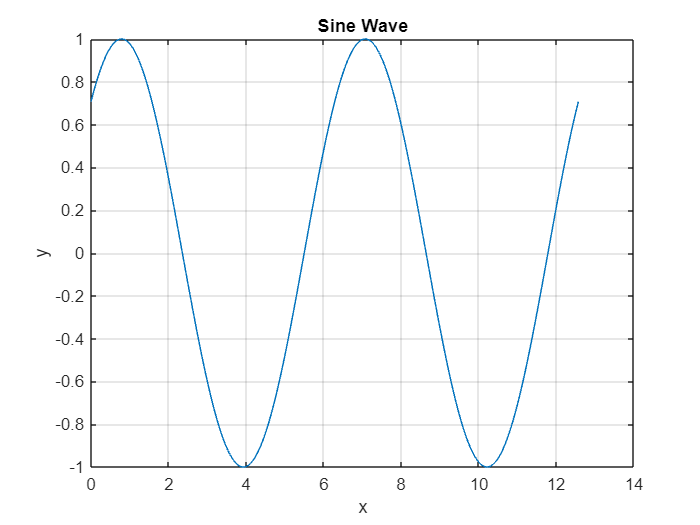

wavelength = 2*pi; % Wellenlänge
amplitude = 1; % Amplitude

y = amplitude * sin(2 * pi * x / wavelength + pi/4);

% Plot
figure;
plot(x, y);
xlabel('x');
ylabel('y');
title('Sine Wave');
grid on;

%Abhängig von der Spalte

function [bildwellen] = wellenEffekt(bildmatrix, wellenlaenge, amplitude)
    [zeilen, spalten, ~] = size(bildmatrix);
    bildwellen = bildmatrix;
    % zeros(size(bildmatrix), 'like', bildmatrix);
    
    for spalte = 1:spalten
        shift = round(amplitude * sin(2 * pi * spalte / wellenlaenge + pi));
        for zeile = 1:zeilen
            neueZeile = zeile + shift;
            neueSpalte = spalte;
            if neueZeile <= 0
                disp(spalte)
                disp(shift)
                disp(zeile)
                disp(neueZeile)
            end
            if neueZeile > 0 && neueZeile <= zeilen
                bildwellen(neueZeile, neueSpalte, :) = bildmatrix(zeile, spalte, :);
            end
        end
    end
end
%Abhängig von der Zeile
function [bildwellen] = wellenEffekt2(bildmatrix, wellenlaenge, amplitude)
    [zeilen, spalten, ~] = size(bildmatrix);
    bildwellen = bildmatrix;
    % zeros(size(bildmatrix), 'like', bildmatrix);
    
    for zeile = 1:zeilen
        shift = round(amplitude * sin(2 * pi * zeile / wellenlaenge + pi));
        for spalte = 1:spalten
            neueSpalte = spalte + shift;
            neueZeile = zeile;
            if neueZeile <= 0
                disp(spalte)
                disp(shift)
                disp(zeile)
                disp(neueZeile)
            end
            if neueSpalte > 0 && neueSpalte <= spalten
                bildwellen(neueZeile, neueSpalte, :) = bildmatrix(zeile, spalte, :);
            end
        end
    end
end